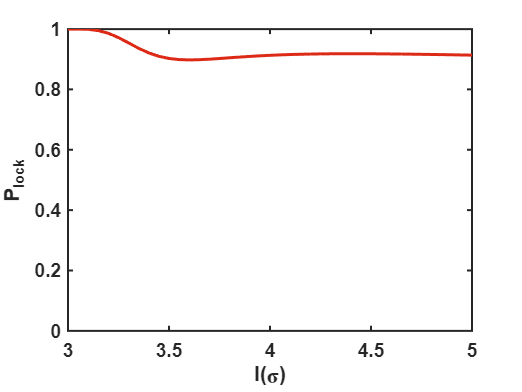

%计算考虑化学作用后的三锁体系
clear all
syms e r o;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=3;


for l = 3:0.05:5
%计算锁死所占成分
    fun1 = @(x2,x1) P(x2).^2.*P(x1-x2).^2.*P(l-x1);
    x2max= @(x1) x1;
    V_lock = 3*integral2(fun1,0,l,0,x2max);

%计算开放所占成分
    fun2 = @(x2,x1) P(l-x1).*P(x1).*P(x1-x2).*P(l-x2).*P(x2);
    x2max= @(x1) x1;
    V_open = 2*integral2(fun2,0,l,0,x2max);
    P_lock = V_lock/(V_lock + V_open);%计算锁死所占比例
    Plock=[Plock,P_lock];
end


%画出锁死概率随l的变化
length=[3:0.05:5];
plot(length, Plock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)

ylim([0 1]);

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('P_{lock}','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5500;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end